



% Reliability of information in a structure between two sessions

clear all
cd /media/DataMOBsRAIDN/PFC_InteroceptiveTuning/DecodingAnalysis
load('DataDecoding_PFC_BR.mat')
Var = 'BR'

Var = 'BR'

Sess1 = 'Wake_Home';
Sess2 = 'Sleep';

Opts.ParamBinLims = [1.5:1:12]

Opts = struct with fields:
     TempBinsize: 1
       BinNumber: 5
    ParamBinLims: [1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000 9.5000 10.5000 11.5000]


MinSamples = 10;

% zscore
for mm = 1:length(spike_dat.(Sess1))
    spike_dat.(Sess1){mm} = zscore(spike_dat.(Sess1){mm}')';
    spike_dat.(Sess2){mm} = zscore(spike_dat.(Sess2){mm}')';
end

cd /media/DataMOBsRAIDN/PFC_InteroceptiveTuning/PFCTuningByVarAndPeriod
T_Sess1 = load('BRTuning_All_Home_PFC_0.2s_6ParamBinNumber.mat','TuningCurves');
T_Sess2 = load('BRTuning_Sleep_PFC_0.2s_6ParamBinNumber.mat','TuningCurves');

for mm = 1:length(spike_dat.(Sess1))
    P1 = cellfun(@(x) x.AnovaInfo,T_Sess1.TuningCurves{mm});
    P2 = cellfun(@(x) x.AnovaInfo,T_Sess2.TuningCurves{mm});
    Good = find(P1<0.05 & P2<0.05);
    spike_dat.(Sess1){mm} = spike_dat.(Sess1){mm}(Good,:);
    spike_dat.(Sess2){mm} = spike_dat.(Sess2){mm}(Good,:);
end

## Recalculate the tuning curves and see if they're the same in both sessions

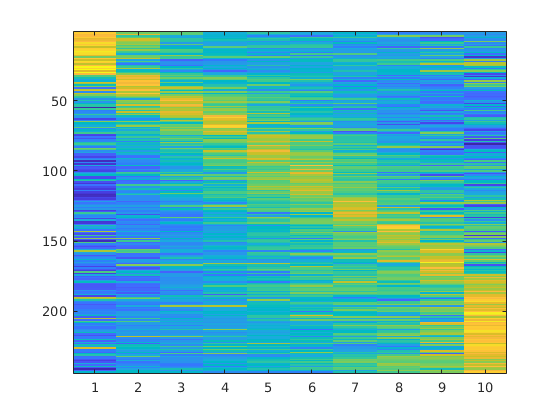

TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI),2);
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end
[~,ind]=max(zscore(TuningAll_1'));
[~,ind]=sort(ind);
figure
imagesc(nanzscore(TuningAll_1(ind,:)')')

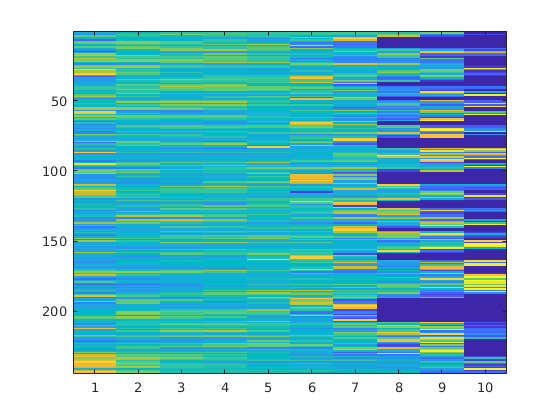


TuningAll_2 = [];
for mm = 1:length(spike_dat.(Sess2))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2) ...
            {mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess2){mm}(:,BinsOI),2);
    end
    TuningAll_2 = [TuningAll_2;Tuning_temp];
end
figure
imagesc(nanzscore(TuningAll_2(ind,:)')')

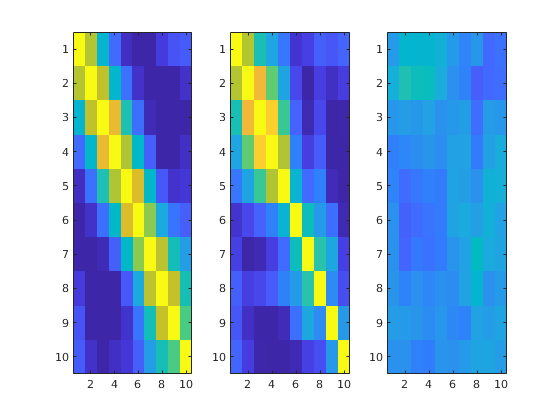


figure
subplot(131)
imagesc(corr(nanzscore(TuningAll_1')','rows','pairwise'))
caxis([-0.5 1])
subplot(132)
imagesc(corr(nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])
subplot(133)
imagesc(corr(nanzscore(TuningAll_1')',nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])

Not enough input arguments.

Error in lasso (line 231)
if ~ismatrix(X) || ~isreal(X) 

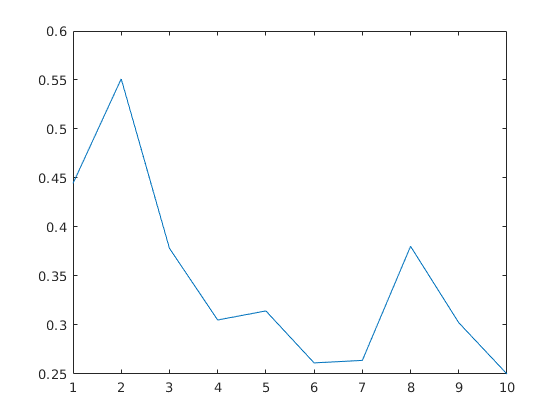

% Do the decoding on the same session
clear Data_todecode TrNumPerMouse
TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.(Sess2))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

for ii = 1:length(Opts.ParamBinLims)-1
    TrialNumToUse = min(TrNumPerMouse(:,ii));
    Data_todecode_temp = [];
    for mm = 1:length(spike_dat.(Sess2))
        Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse))];
    end
    [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
    PropCorr(ii) = nanmean(ind==ii);

end
figure
plot(PropCorr)

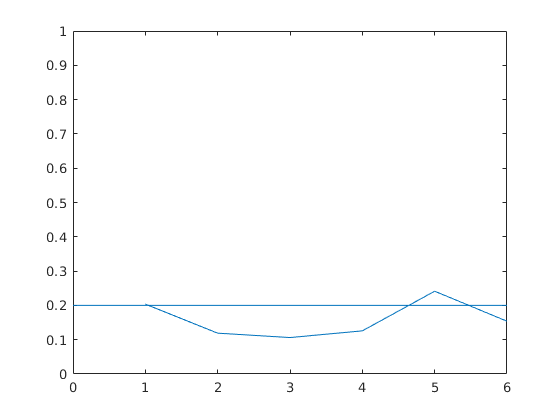

% Do the decoding on the same session
clear Data_todecode TrNumPerMouse
for mm = 1:length(spike_dat.(Sess2))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2){mm}<Opts.ParamBinLims(ii+1));
        Data_todecode{mm}{ii} = spike_dat.(Sess2){mm}(:,BinsOI);
    end
end

for mm = 1:length(spike_dat.(Sess2))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

clear PropCorr
for ii = 1:length(Opts.ParamBinLims)-1
    TrialNumToUse = min(TrNumPerMouse(:,ii));
    Data_todecode_temp = [];
    for mm = 1:length(spike_dat.(Sess2))
        Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse))];
    end
    [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
    PropCorr(ii) = nanmean(ind==ii);

end

plot(PropCorr)
ylim([0 1])
xlim([0 6])
line(xlim,[0.2 0.2])

% Now do the stats
clear PropCorr_te PropCorr_tr

for perm = 1:300
    % Do the decoding on the same session
    clear Data_todecode TrNumPerMouse
    TuningAll_1 = [];
    TuningAll_Full = [];
    for mm = 1:length(spike_dat.(Sess1))
        clear Tuning_temp Tuning_tempFull
        for ii = 1:length(Opts.ParamBinLims)-1
            BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
            order = randperm(length(BinsOI),length(BinsOI));
            BinsOI = BinsOI(order);
            Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
            Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
            Tuning_tempFull(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI),2);
        end
        TuningAll_1 = [TuningAll_1;Tuning_temp];
        TuningAll_Full = [TuningAll_Full;Tuning_tempFull];

    end

    for mm = 1:length(spike_dat.(Sess2))
        TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
    end

    for ii = 1:length(Opts.ParamBinLims)-1
        TrialNumToUse_Tr(ii) = min(TrNumPerMouse(:,ii));
        Data_todecode_temp = [];
        for mm = 1:length(spike_dat.(Sess2))
            Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse_Tr(ii)))];
        end
        [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
        PropCorr_tr(perm,ii) = nanmean(abs(ind-ii));

    end
    PropCorr_tr(:,TrialNumToUse_Tr<MinSamples) = NaN;


    % Do the decoding on the same session
    clear Data_todecode TrNumPerMouse
    for mm = 1:length(spike_dat.(Sess2))
        clear Tuning_temp
        for ii = 1:length(Opts.ParamBinLims)-1
            BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2){mm}<Opts.ParamBinLims(ii+1));
            Data_todecode{mm}{ii} = spike_dat.(Sess2){mm}(:,BinsOI);
        end
    end

    for mm = 1:length(spike_dat.(Sess2))
        TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
    end

    clear PropCorr
    for ii = 1:length(Opts.ParamBinLims)-1
        TrialNumToUse_Te(ii) = min(TrNumPerMouse(:,ii));
        Data_todecode_temp = [];
        for mm = 1:length(spike_dat.(Sess2))
            Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse_Te(ii)))];
        end
        [val,ind] = max(corr(TuningAll_Full,Data_todecode_temp));
        PropCorr_te(perm,ii) = nanmean(abs(ind-ii));
    end
    PropCorr_te(:,TrialNumToUse_Te<MinSamples) = NaN;
end


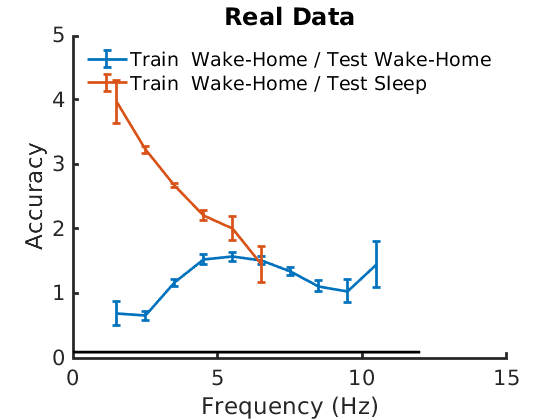


figure
errorbar(Opts.ParamBinLims(1:end-1),nanmean(PropCorr_tr),std(PropCorr_tr),'linewidth',2)
hold on
errorbar(Opts.ParamBinLims(1:end-1),nanmean(PropCorr_te),std(PropCorr_te),'linewidth',2)
%ylim([0 1])
%xlim([1 12])
line(xlim,[1 1]/length(Opts.ParamBinLims),'color','k')
xlabel('Frequency (Hz)')
makepretty
ylabel('Accuracy')
legend({['Train  ' strrep(Sess1,'_','-') ' / Test ' strrep(Sess1,'_','-')],...
    ['Train  ' strrep(Sess1,'_','-') ' / Test ' strrep(Sess2,'_','-')]})
legend('boxoff')
title('Real Data')



A{1} = nanmean(PropCorr_tr');
A{2} = nanmean(PropCorr_te');

% Now do the stats
clear PropCorr_te PropCorr_tr
for perm = 1:300

    % Do the decoding on the same session
    clear Data_todecode TrNumPerMouse
    TuningAll_1 = [];
    TuningAll_Full= [];
    for mm = 1:length(spike_dat.(Sess1))
        clear Tuning_temp Tuning_tempFull
        varoi_rand = VarOfInterest.(Sess1){mm}(randperm(length(VarOfInterest.(Sess1){mm}),length(VarOfInterest.(Sess1){mm})));
        for ii = 1:length(Opts.ParamBinLims)-1
            BinsOI = find(varoi_rand>Opts.ParamBinLims(ii) & varoi_rand<Opts.ParamBinLims(ii+1));
            Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
            Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
            Tuning_tempFull(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI),2);
        end
        TuningAll_1 = [TuningAll_1;Tuning_temp];
        TuningAll_Full = [TuningAll_Full;Tuning_tempFull];

    end
    % randomize neurons
    TuningAll_1 = TuningAll_1(randperm(size(TuningAll_1,1),size(TuningAll_1,1)),:);
    TuningAll_Full = TuningAll_Full(randperm(size(TuningAll_Full,1),size(TuningAll_Full,1)),:);

    for mm = 1:length(spike_dat.(Sess2))
        TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
    end

    for ii = 1:length(Opts.ParamBinLims)-1
        TrialNumToUse_Tr(ii) = min(TrNumPerMouse(:,ii));
        Data_todecode_temp = [];
        for mm = 1:length(spike_dat.(Sess2))
            Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse_Tr(ii)))];
        end
        [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
        PropCorr_tr(perm,ii) = nanmean(abs(ind-ii));

    end
    PropCorr_tr(:,TrialNumToUse_Tr<MinSamples) = NaN;


    % Do the decoding on the same session
    clear Data_todecode TrNumPerMouse
    for mm = 1:length(spike_dat.(Sess2))
        clear Tuning_tem
        varoi_rand = VarOfInterest.(Sess2){mm}(randperm(length(VarOfInterest.(Sess2){mm}),length(VarOfInterest.(Sess2){mm})));
        for ii = 1:length(Opts.ParamBinLims)-1
            BinsOI = find(varoi_rand>Opts.ParamBinLims(ii) & varoi_rand<Opts.ParamBinLims(ii+1));
            Data_todecode{mm}{ii} = spike_dat.(Sess2){mm}(:,BinsOI);
        end
    end

    for mm = 1:length(spike_dat.(Sess2))
        TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
    end

    clear PropCorr
    for ii = 1:length(Opts.ParamBinLims)-1
        TrialNumToUse_Te(ii) = min(TrNumPerMouse(:,ii));
        Data_todecode_temp = [];
        for mm = 1:length(spike_dat.(Sess2))
            Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse_Te(ii)))];
        end
        [val,ind] = max(corr(TuningAll_Full,Data_todecode_temp));
        PropCorr_te(perm,ii) = nanmean(abs(ind-ii));

    end
    PropCorr_te(:,TrialNumToUse_Te<MinSamples) = NaN;

end

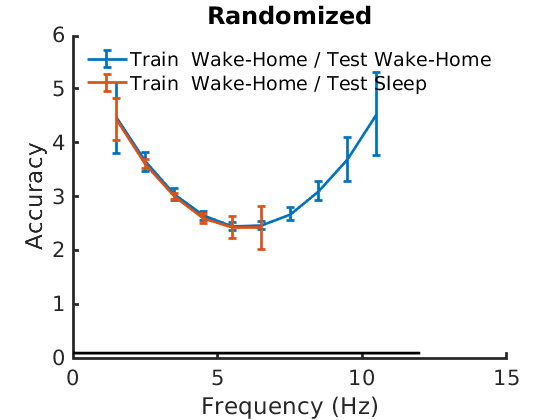

figure
errorbar(Opts.ParamBinLims(1:end-1),nanmean(PropCorr_tr),std(PropCorr_tr),'linewidth',2)
hold on
errorbar(Opts.ParamBinLims(1:end-1),nanmean(PropCorr_te),std(PropCorr_te),'linewidth',2)
%ylim([0 1])
%xlim([1 12])
line(xlim,[1 1]/length(Opts.ParamBinLims),'color','k')
xlabel('Frequency (Hz)')
makepretty
ylabel('Accuracy')
legend({['Train  ' strrep(Sess1,'_','-') ' / Test ' strrep(Sess1,'_','-')],...
    ['Train  ' strrep(Sess1,'_','-') ' / Test ' strrep(Sess2,'_','-')]})
legend('boxoff')
title('Randomized')



A{3} = nanmean(PropCorr_tr');
A{4} = nanmean(PropCorr_te');

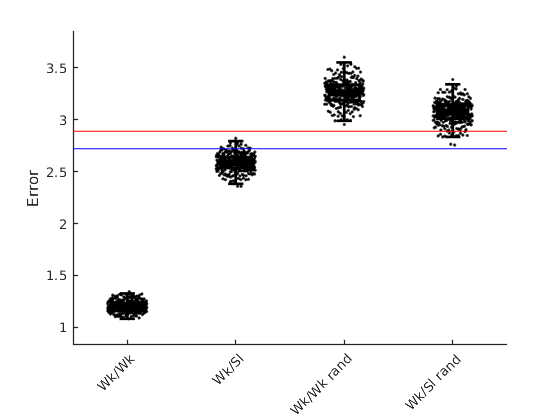

figure
MakeSpreadAndBoxPlot_BM(A,[],[],{'Wk/Wk','Wk/Sl',['Wk/' ...
    'Wk rand'],'Wk/Sl rand'},1,0)
line(xlim,[1 1]/(length(Opts.ParamBinLims)-1),'color','k')
ylabel('Error')
line(xlim,[1 1]*prctile(A{2},95),'color','b')
line(xlim,[1 1]*prctile(A{4},5),'color','r')